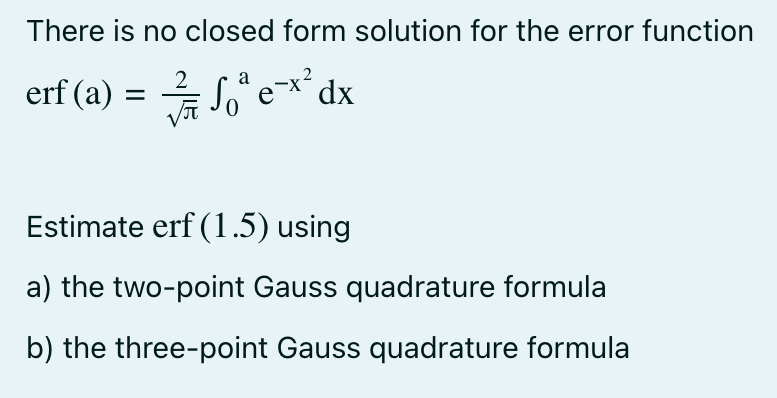

a = 0;
b = 1.5;

a1 = (b + a) / 2;
a2 = (b - a) / 2;

f =@(xd) ((2 / sqrt(pi)) * exp(-(a1 + a2 .* xd) .^ 2)) * a2;

% two-point
c0 = 1;
c1 = 1;
x0 = -1 / sqrt(3);
x1 = 1 / sqrt(3);
I_gauss2 = c0 * f(x0) + c1 * f(x1);
fprintf('I_gauss2 = %.4f', I_gauss2)

I_gauss2 = 0.9742


% three-point
c0 = 5/9;
c1 = 8/9;
c2 = 5/9;
x0 = -sqrt(3/5);
x1 = 0.0;
x2 = sqrt(3/5);

I_gauss3 = c0 * f(x0) + c1 * f(x1) + c2 * f(x2);
fprintf('I_gauss3 = %.4f', I_gauss3)

I_gauss3 = 0.9655